MathTools HW2

2024-9-30

Question 1

addpath('hw2-files/');
load('colMatch.mat');

## a)

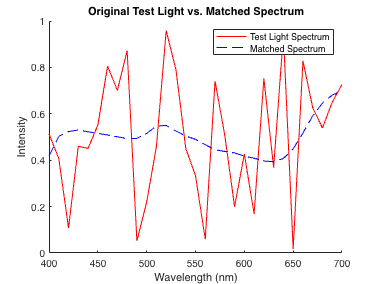

testLight = rand(31, 1); 
knobSettings = humanColorMatcher(testLight, P); 

%matching the spectrum
matchedSpectrum = P * knobSettings;

%Plotting 
figure; hold on;
plot(400:10:700, testLight, 'r', 'DisplayName', 'Test Light Spectrum'); 
plot(400:10:700, matchedSpectrum, 'b--', 'DisplayName', 'Matched Spectrum'); 
xlabel('Wavelength (nm)');
ylabel('Intensity');
legend;
title('Original Test Light vs. Matched Spectrum');
hold off;

## b)

testLights_b = eye(31); 

%empty holder
knobSettings_matrix = zeros(3, 31); 

for i = 1:31
    knobSettings_matrix(:, i) = humanColorMatcher(testLights_b(:, i), P);
end

M = knobSettings_matrix / testLights_b; %since can't use inv()

randomTestLight = rand(31, 1); 
predictedKnob = M * randomTestLight;

actualKnob = humanColorMatcher(randomTestLight, P);

disp('Predicted knob settings (using matrix M):');

Predicted knob settings (using matrix M):


disp(predictedKnob);

    0.7492
   -0.0497
    0.7847



disp('Actual knob settings (using humanColorMatcher):');

Actual knob settings (using humanColorMatcher):


disp(actualKnob);

    0.7492
   -0.0497
    0.7847




if norm(predictedKnob - actualKnob) < 1e-6
    disp('The matrix M finely predicts the humanColorMatcher responses.');
else
    disp('There is a discrepancy between the predicted and actual knob settings.');
end

The matrix M finely predicts the humanColorMatcher responses.


## c)

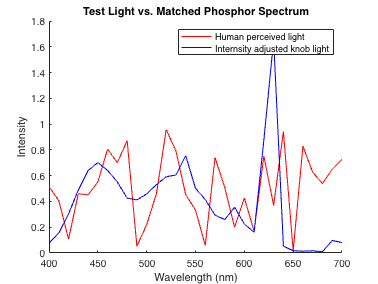


phosphorInt = (Cones * Phosphors) \ (Cones * testLight);

human_light = testLight;  % The test light spectrum
knob_light = Phosphors * phosphorInt;  % The spectrum generated by the phosphor mixture

figure; hold on;
plot(400:10:700, human_light, 'r', 'DisplayName', 'Human perceived light');
plot(400:10:700, knob_light, 'b', 'DisplayName', 'Internsity adjusted knob light');
xlabel('Wavelength (nm)');
ylabel('Intensity');
legend;
title('Test Light vs. Matched Phosphor Spectrum');
hold off;

## d i)

load('colMatch.mat');

for i = 1:5
testLightD = rand(31,1);

fprintf('Test light %d:\n', i);

deficientKnob = altHumanColorMatcher(testLightD, P);
normalKnob = humanColorMatcher(testLightD, P);

disp('Knob settings for color-deficient observer:');
disp(deficientKnob);

disp('Knob settings for normal observer:');
disp(normalKnob);

end

Test light 1:


Knob settings for color-deficient observer:


    0.9127
   -3.2543
    3.5225



Knob settings for normal observer:


    1.0012
    0.1911
    0.4583



Test light 2:


Knob settings for color-deficient observer:


    1.2843
   -3.1528
    3.0261



Knob settings for normal observer:


    1.3718
    0.2516
   -0.0015



Test light 3:


Knob settings for color-deficient observer:


    0.6612
   -2.2332
    2.4209



Knob settings for normal observer:


    0.7325
    0.5428
   -0.0480



Test light 4:


Knob settings for color-deficient observer:


    1.1139
   -2.9590
    2.9889



Knob settings for normal observer:


    1.1944
    0.1742
    0.2023



Test light 5:


Knob settings for color-deficient observer:


    0.9880
   -2.2953
    2.1207



Knob settings for normal observer:


    1.0505
    0.1357
   -0.0414



For normal observers, they adjust intensities of all three primaries to match the all runs of test light.

For color deficient observers, the knob settings for typically the red and green primaries, differ significantly from the normal observer's. 

So the key difference is that the color deficient observers have imparied intensity to certian wavelength, and thus their knob settings for matching certain color are different from those of normal observers.  

## d ii)

load('colMatch.mat');

for i = 1:5
testLightDii = rand(31,1);

deficientKnob_ii = altHumanColorMatcher(testLightDii, P);
normalKnob_ii = humanColorMatcher(testLightDii, P);

coneAbsorption = Cones * testLightDii;

%For deficient observers
primaryMixture_deficient = P * deficientKnob_ii;
coneAbsorption_deficient = Cones * primaryMixture_deficient; 

%For normal observers
primaryMixture_normal = P * normalKnob_ii;
coneAbsorption_normal = Cones * primaryMixture_normal; 

fprintf('Test light %d:\n', i);

disp('Cone absorptions for test light:');
disp(coneAbsorption);

disp('Cone absorptions for test light (deficient observer):');
disp(coneAbsorption_deficient);

disp('Cone absorptions for test light (normal observer):');
disp(coneAbsorption_normal);


disp('Cone absorptions for primary mixture (color-deficient observer):');
disp(primaryMixture_deficient);

disp('Cone absorptions for primary mixture (normal observer):');
disp(primaryMixture_normal);

end 

Test light 1:


Cone absorptions for test light:


    5.5152
    4.2759
    3.4151



Cone absorptions for test light (deficient observer):


    1.1625
    4.2759
    3.4151



Cone absorptions for test light (normal observer):


    5.5152
    4.2759
    3.4151



Cone absorptions for primary mixture (color-deficient observer):


    0.3542
    0.4162
    0.4431
    0.4780
    0.4658
    0.4856
    0.5021
    0.5236
    0.5624
    0.6506
    0.8528
    1.1430
    1.2799
    1.1289
    0.8199
    0.5136
    0.2478
    0.0110
   -0.2077
   -0.4197
   -0.6264
   -0.7790
   -0.8668
   -0.9250
   -0.9596
   -0.9537
   -0.8920
   -0.7908
   -0.6956
   -0.6223
   -0.5897



Cone absorptions for primary mixture (normal observer):


    0.4308
    0.5214
    0.5417
    0.5447
    0.5372
    0.5256
    0.5148
    0.5011
    0.4841
    0.4696
    0.4607
    0.4489
    0.4254
    0.4137
    0.4284
    0.4541
    0.4642
    0.4725
    0.4960
    0.5205
    0.5358
    0.5482
    0.5473
    0.5523
    0.5734
    0.6210
    0.6905
    0.7612
    0.8111
    0.8393
    0.8540



Test light 2:


Cone absorptions for test light:


    5.2985
    4.5596
    3.2876



Cone absorptions for test light (deficient observer):


    1.8888
    4.5596
    3.2876



Cone absorptions for test light (normal observer):


    5.2985
    4.5596
    3.2876



Cone absorptions for primary mixture (color-deficient observer):


    0.3428
    0.4014
    0.4260
    0.4584
    0.4475
    0.4663
    0.4824
    0.5043
    0.5432
    0.6291
    0.8233
    1.1014
    1.2383
    1.1080
    0.8304
    0.5526
    0.3095
    0.0922
   -0.1095
   -0.3064
   -0.4993
   -0.6415
   -0.7230
   -0.7764
   -0.8075
   -0.8013
   -0.7420
   -0.6456
   -0.5549
   -0.4852
   -0.4533



Cone absorptions for primary mixture (normal observer):


    0.4028
    0.4838
    0.5032
    0.5106
    0.5034
    0.4977
    0.4923
    0.4867
    0.4818
    0.4874
    0.5161
    0.5577
    0.5689
    0.5477
    0.5238
    0.5059
    0.4790
    0.4537
    0.4417
    0.4301
    0.4111
    0.3981
    0.3847
    0.3808
    0.3933
    0.4323
    0.4976
    0.5702
    0.6254
    0.6597
    0.6776



Test light 3:


Cone absorptions for test light:


    5.2566
    4.4478
    4.0087



Cone absorptions for test light (deficient observer):


    1.9430
    4.4478
    4.0087



Cone absorptions for test light (normal observer):


    5.2566
    4.4478
    4.0087



Cone absorptions for primary mixture (color-deficient observer):


    0.4409
    0.5256
    0.5564
    0.5874
    0.5737
    0.5859
    0.5952
    0.6061
    0.6296
    0.6947
    0.8566
    1.0898
    1.1861
    1.0397
    0.7682
    0.5065
    0.2776
    0.0742
   -0.1064
   -0.2792
   -0.4495
   -0.5752
   -0.6509
   -0.6998
   -0.7231
   -0.7020
   -0.6265
   -0.5176
   -0.4208
   -0.3499
   -0.3186



Cone absorptions for primary mixture (normal observer):


    0.4992
    0.6057
    0.6314
    0.6382
    0.6280
    0.6164
    0.6048
    0.5889
    0.5700
    0.5569
    0.5581
    0.5614
    0.5356
    0.4953
    0.4702
    0.4611
    0.4423
    0.4256
    0.4293
    0.4365
    0.4352
    0.4351
    0.4256
    0.4248
    0.4439
    0.4968
    0.5781
    0.6639
    0.7261
    0.7627
    0.7804



Test light 4:


Cone absorptions for test light:


    6.4006
    5.1102
    2.8099



Cone absorptions for test light (deficient observer):


    1.9952
    5.1102
    2.8099



Cone absorptions for test light (normal observer):


    6.4006
    5.1102
    2.8099



Cone absorptions for primary mixture (color-deficient observer):


    0.2679
    0.3035
    0.3235
    0.3605
    0.3517
    0.3796
    0.4046
    0.4408
    0.5002
    0.6173
    0.8653
    1.2196
    1.4139
    1.2885
    0.9773
    0.6550
    0.3729
    0.1191
   -0.1252
   -0.3675
   -0.6037
   -0.7778
   -0.8735
   -0.9370
   -0.9798
   -0.9892
   -0.9419
   -0.8501
   -0.7574
   -0.6824
   -0.6468



Cone absorptions for primary mixture (normal observer):


    0.3454
    0.4099
    0.4233
    0.4280
    0.4239
    0.4201
    0.4175
    0.4180
    0.4210
    0.4342
    0.4684
    0.5171
    0.5491
    0.5647
    0.5812
    0.5947
    0.5919
    0.5863
    0.5870
    0.5841
    0.5725
    0.5654
    0.5576
    0.5582
    0.5717
    0.6046
    0.6596
    0.7207
    0.7675
    0.7968
    0.8143



Test light 5:


Cone absorptions for test light:


    5.7205
    4.4484
    2.3887



Cone absorptions for test light (deficient observer):


    2.7692
    4.4484
    2.3887



Cone absorptions for test light (normal observer):


    5.7205
    4.4484
    2.3887



Cone absorptions for primary mixture (color-deficient observer):


    0.2438
    0.2797
    0.2951
    0.3197
    0.3134
    0.3306
    0.3464
    0.3702
    0.4096
    0.4884
    0.6557
    0.8948
    1.0283
    0.9538
    0.7603
    0.5583
    0.3780
    0.2150
    0.0591
   -0.0968
   -0.2507
   -0.3638
   -0.4266
   -0.4669
   -0.4914
   -0.4907
   -0.4490
   -0.3774
   -0.3081
   -0.2538
   -0.2271



Cone absorptions for primary mixture (normal observer):


    0.2958
    0.3510
    0.3619
    0.3649
    0.3618
    0.3578
    0.3550
    0.3549
    0.3565
    0.3657
    0.3898
    0.4242
    0.4489
    0.4689
    0.4949
    0.5179
    0.5247
    0.5280
    0.5362
    0.5408
    0.5373
    0.5361
    0.5322
    0.5347
    0.5480
    0.5770
    0.6239
    0.6750
    0.7135
    0.7371
    0.7517



From my observation, the normal observers, in general, they have a balanced absorption across L,M and S cones. The absorption of normal observers are the same as tested cone absorption, since the normal observers perceives the two as identical.

For deficient observers, they are showing a reduced response in one of the cone, which in general across 5 test lights tend to be the L cone. They primary mixture fro the color-deficient observers also lead to different cone absorption than the normal observer and the tested cone absorption, which is influencing their color perception. 

To diagnose, I think the deficient observers have protanopia, where they have deficit L-cone, leading to difficulties perceiving red hues. 